BackTestV1

clear
tic

T = readtable('dowPortfolio.xlsx');

PriceTT = table2timetable (T) ;


%SMA Signal
LeadDays = 2 ; 
LagDays = 20 ;

SMALead = movavg (PriceTT, 'simple', LeadDays) ;
SMALag = movavg (PriceTT, 'simple', LagDays) ;

SMASignalTT = PriceTT ;
SMASignalTT.Variables = SMALead.Variables >= SMALag.Variables ;
SMASignalFinalTT = SMASignalTT ;
SMASignalFinal = SMASignalFinalTT.Variables ;
SMASignal = SMASignalTT.Variables ;
SMASignalFinal (2:end, :) = SMASignal (1:end-1, :)

SMASignalFinal =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     0     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     0     1     1
     1     1     1     1     1     1     1     1     1     0     1     1     0     1     1     1     1     1     1     0     1     1     1     1     1     0     1     1     1     1     0
     1     1     1     0     1     0     1     0     0     0     1     0     0     1     1     1     1     0     1     1     0     1     1     1     1     1     1     0     1     0     0
     1     1     1     1     0     0     1     0     1     1     1     0     1     1     1     1     1     1     1     1     0     1     1     1     1     0     1     0     1     0     1
     1     1     1     1     0     0     1     0

SMASignalFinal (1, :) = 0

SMASignalFinal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     0     1     1
     1     1     1     1     1     1     1     1     1     0     1     1     0     1     1     1     1     1     1     0     1     1     1     1     1     0     1     1     1     1     0
     1     1     1     0     1     0     1     0     0     0     1     0     0     1     1     1     1     0     1     1     0     1     1     1     1     1     1     0     1     0     0
     1     1     1     1     0     0     1     0     1     1     1     0     1     1     1     1     1     1     1     1     0     1     1     1     1     0     1     0     1     0     1
     1     1     1     1     0     0     1     0

SMASignalFinalTT.Variables = SMASignalFinal

SMASignalFinalTT = 251×31 timetable
       Dates       DJI    AA    AIG    AXP    BA    C    CAT    DD    DIS    GE    GM    HD    HON    HPQ    IBM    INTC    JNJ    JPM    KO    MCD    MMM    MO    MRK    MSFT    PFE    PG    T    UTX    VZ    WMT    XOM
    ___________    ___    __    ___    ___    __    _    ___   


%Strategy
TradingCosts = [0.15/100, 0.2/100] ;

SMAInitWeights = ComputeInitialWeights (SMASignalFinalTT (20, :)) ;
SMArebalanceFcn = @(w,s) CrossoverRebalanceFcn (w,s) ;
SMAStrategy = backtestStrategy ('SMAStrategyBacktest', SMArebalanceFcn, ...
    'TransactionCosts',TradingCosts, "RebalanceFrequency", 1, ...
    "LookbackWindow", 2, "InitialWeights",SMAInitWeights ) 

SMAStrategy =   backtestStrategy with properties:

                  Name: "SMAStrategyBacktest"
          RebalanceFcn: @(w,s)CrossoverRebalanceFcn(w,s)
    RebalanceFrequency: 1
      TransactionCosts: [0.0015 0.0020]
        LookbackWindow: 2
        InitialWeights: [0.0323 0.0323 0 0.0323 0 0 0.0323 0 0.0323 0 0.0323 0 0.0323 0.0323 0 0 0 0.0323 0.0323 0.0323 0 0 0.0323 0.0323 0.0323 0.0323 0.0323 0.0323 0.0323 0.0323 0.0323]



%Set-up backtest engine
bt = backtestEngine(SMAStrategy, 'RiskFreeRate', 0.02/365, ...
    "InitialPortfolioValue", 10^2, "CashBorrowRate", 0.18/365)

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 5.4795e-05
           CashBorrowRate: 4.9315e-04
    InitialPortfolioValue: 100
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% run the strategy backtest
startIdx = 20 ;

bt = runBacktest (bt, PriceTT, SMASignalFinalTT, 'start', startIdx) 

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 5.4795e-05
           CashBorrowRate: 4.9315e-04
    InitialPortfolioValue: 100
                NumAssets: 31
                  Returns: [231×1 timetable]
                Positions: [1×1 struct]
                 Turnover: [231×1 timetable]
                  BuyCost: [231×1 timetable]
                 SellCost: [231×1 timetable]



% Summary
SummaryTable = summary (bt)

SummaryTable = 9×1 table
                       SMAStrategyBacktest
                       ___________________

    TotalReturn               0.12547     
    SharpeRatio                0.1064     
    Volatility              0.0043952     
    AverageTurnover                 0     
    MaxTurnover                     0     
    AverageReturn          0.00052143     
    MaxDrawdown              0.050404     
    AverageBuyCost                  0     
    AverageSellCost                 0     



%Plot cumulative return
dailyRet = bt.Returns ;
portfolioValue = ret2tick (dailyRet)

portfolioValue = 231×1 timetable
       Time        SMAStrategyBacktest
    ___________    ___________________

    01-Feb-2006           1.0041      
    02-Feb-2006          0.99815      
    03-Feb-2006            0.996      
    06-Feb-2006          0.99703      
    07-Feb-2006           0.9944      
    08-Feb-2006           1.0018      
    09-Feb-2006           1.0015      
    10-Feb-2006           1.0016      
    13-Feb-2006           1.0003      
    14-Feb-2006           1.0087      
    15-Feb-2006           1.0114      
    16-Feb-2006           1.0178      
    17-Feb-2006           1.0173      
    21-Feb-2006           1.0127      
    22-Feb-2006    

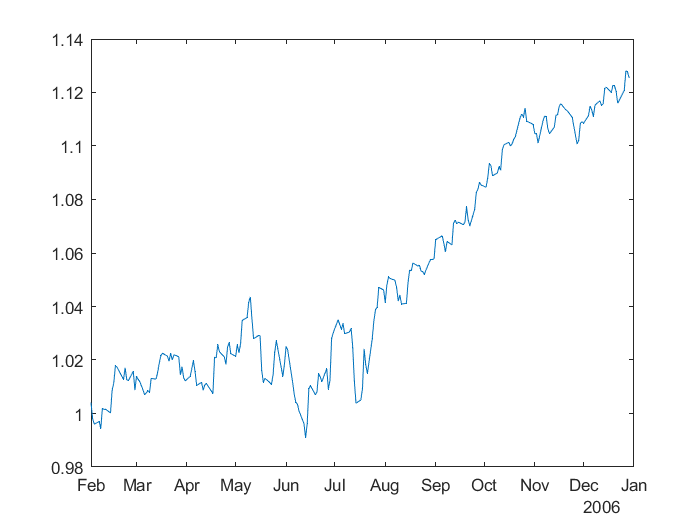

plot (portfolioValue.Time, portfolioValue.Variables)


%Asset area plot

time = bt.Positions.SMAStrategyBacktest.Time 

time = 232×1 datetime array
   31-Jan-2006
   01-Feb-2006
   02-Feb-2006
   03-Feb-2006
   06-Feb-2006
   07-Feb-2006
   08-Feb-2006
   09-Feb-2006
   10-Feb-2006
   13-Feb-2006
   14-Feb-2006
   15-Feb-2006
   16-Feb-2006
   17-Feb-2006
   21-Feb-2006
   22-Feb-2006
   23-Feb-2006
   24-Feb-2006
   27-Feb-2006
   28-Feb-2006
   01-Mar-2006
   02-Mar-2006
   03-Mar-2006
   06-Mar-2006
   07-Mar-2006
   08-Mar-2006
   09-Mar-2006
   10-Mar-2006
   13-Mar-2006
   14-Mar-2006


positions = bt.Positions.SMAStrategyBacktest.Variables

positions =    35.4839    3.2258    3.2258         0    3.2258         0         0    3.2258         0    3.2258         0    3.2258         0    3.2258    3.2258         0         0         0    3.2258    3.2258    3.2258         0         0    3.2258    3.2258    3.2258    3.2258    3.2258    3.2258    3.2258    3.2258    3.2258
   35.4858    3.2523    3.2013         0    3.2365         0         0    3.2895         0    3.2207         0    3.2841         0    3.3033    3.2311         0         0         0    3.2369    3.2356    3.2862         0         0    3.2408    3.2129    3.2716    3.2580    3.3006    3.2053    3.2406    3.2280    3.1849
   35.4878    3.2220    3.1544         0    3.2327         0         0    3.2488         0    3.1988         0    3.1646         0    3.2354    3.1985         0         0         0    3.2455    3.2144    3.2664         0         0    3.1620    3.1718    3.2379    3.2490    3.2966    3.1917    3.2144    3.2373    3.1849
   35.4897    3.2047    3

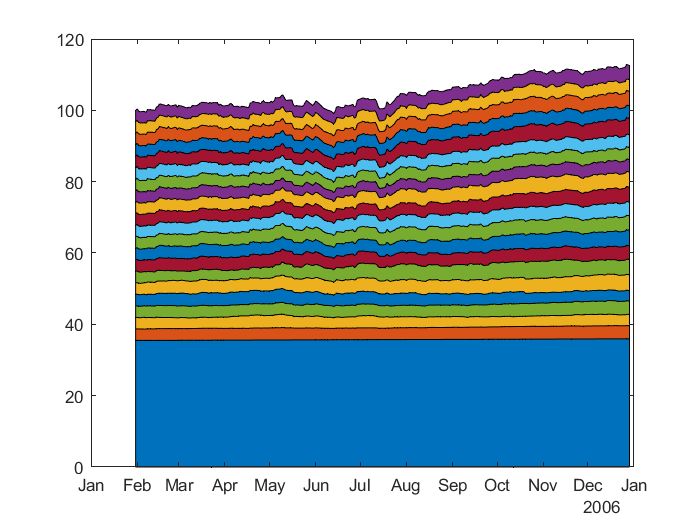

h =   1×32 Area array:

    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area    Area



h = area (time, positions)

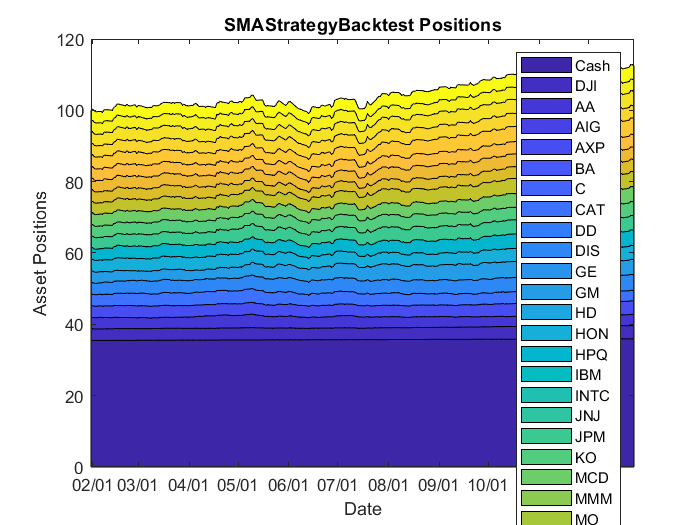


assetAreaPlot (bt, 'SMAStrategyBacktest')


toc

Elapsed time is 2.052143 seconds.


Local functions

function InitialWeights = ComputeInitialWeights (SignalTT) 
% Compute initial weights based on most recent signal.

Signals = SignalTT.Variables ;
nAssets = size (Signals, 2) ;
FinalSignal = Signals (end, :) ;
buys = FinalSignal == 1 ;
InitialWeights = zeros (1, nAssets) ;
InitialWeights (buys) = 1/nAssets ;

end


function new_weights = CrossoverRebalanceFcn (Current_Weights, SignalTT) 
% Signal crossover rebalance function.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Start with current weights
new_weights = Current_Weights ;

% Sell existing long positions where the signal has turned from 1 to 0
idx = CrossoverSignal == 0 ;
new_weights (idx) = 0 ;

% Find new crossover (signal has turned from 0 to 1)
idx = and (CrossoverSignal (end-1,:) == 0, CrossoverSignal (end,:) == 0 ) ;

% Bet sizing
AvailableCapital = 1 - sum (new_weights) ;
UninvestedAssets = 1 - sum (new_weights == 0) ;
new_weights (idx) = AvailableCapital / UninvestedAssets ;

end


function assetAreaPlot(backtester,strategyName)
% Plot the asset allocation as an area plot.

t = backtester.Positions.(strategyName).Time;
positions = backtester.Positions.(strategyName).Variables;
h = area(t,positions);
title(sprintf('%s Positions',strrep(strategyName,'_',' ')));
xlabel('Date');
ylabel('Asset Positions');
datetick('x','mm/dd','keepticks');
xlim([t(1) t(end)])
oldylim = ylim;
ylim([0 oldylim(2)]);
cm = parula(numel(h));
for i = 1:numel(h)
    set(h(i),'FaceColor',cm(i,:));
end
legend(backtester.Positions.(strategyName).Properties.VariableNames)

end